# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

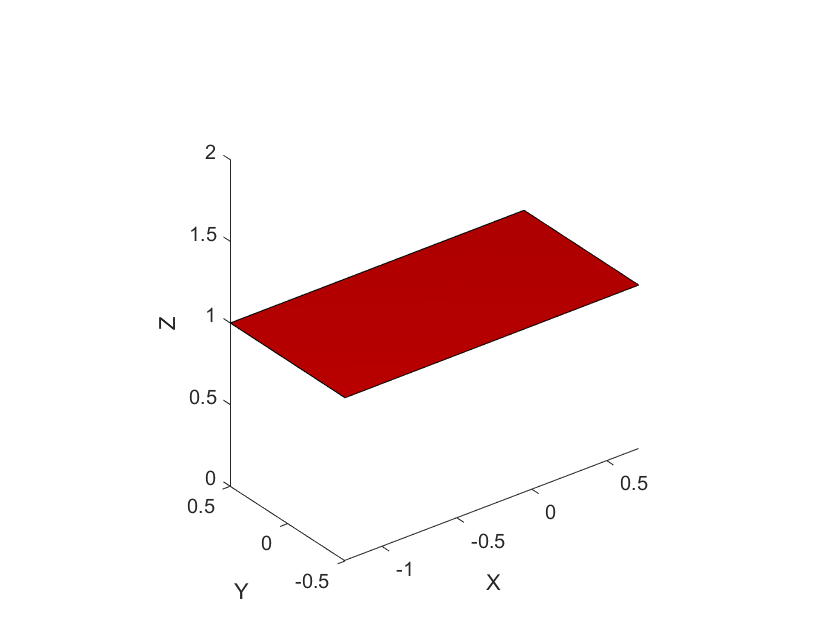

table_h = 1.0;
table_length = 2.5;
table_width = 1.0;
x = [-table_length/2 table_length/3.5 table_length/3.5 -table_length/2];
y = [-table_width/2 -table_width/2 table_width/2 table_width/2];
z = [table_h table_h table_h table_h];
axis([-2 2 -2 2 0 4]), axis('equal');
patch(x,y,z,'red')
camlight('headlight');
material('dull');
xlabel('X'), ylabel('Y'), zlabel('Z')

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

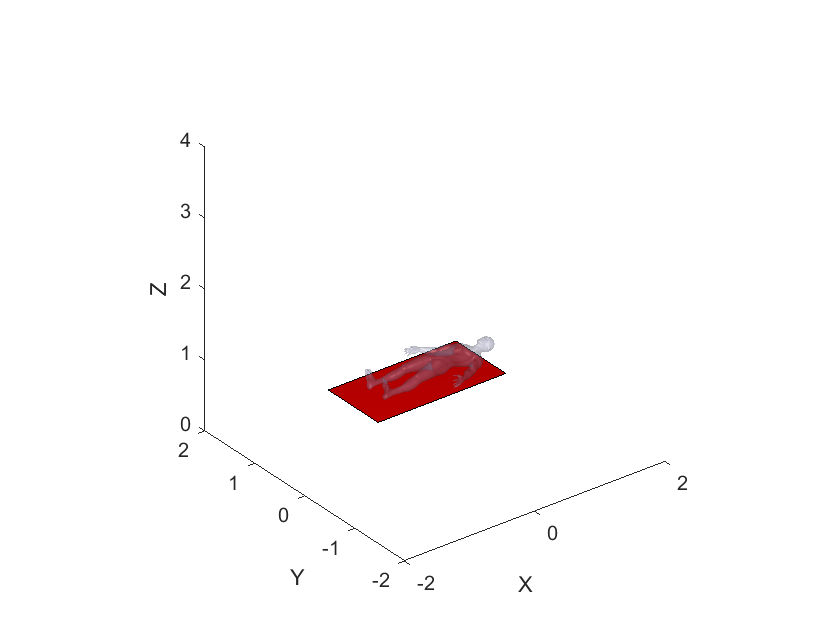

[VB,FB] = readOBJ('Human_body.obj','Quads',true);
person_height = 1.8;
VB = VB .* (person_height/max(VB(:, 2)));
VB = [VB ones(size(VB, 1), 1)];
VB = transl(-person_height/2, 0, table_h-min(VB(:, 3)))*trotz(-90, 'deg')*VB';
VB = (VB(1:3, :))';
p = patch('Faces',FB,'Vertices',VB, 'FaceColor',       [0.8 0.8 1.0], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15, ...
         'FaceAlpha', 0.25);
axis([-2 2 -2 2 0 4]);

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

## put your code Here

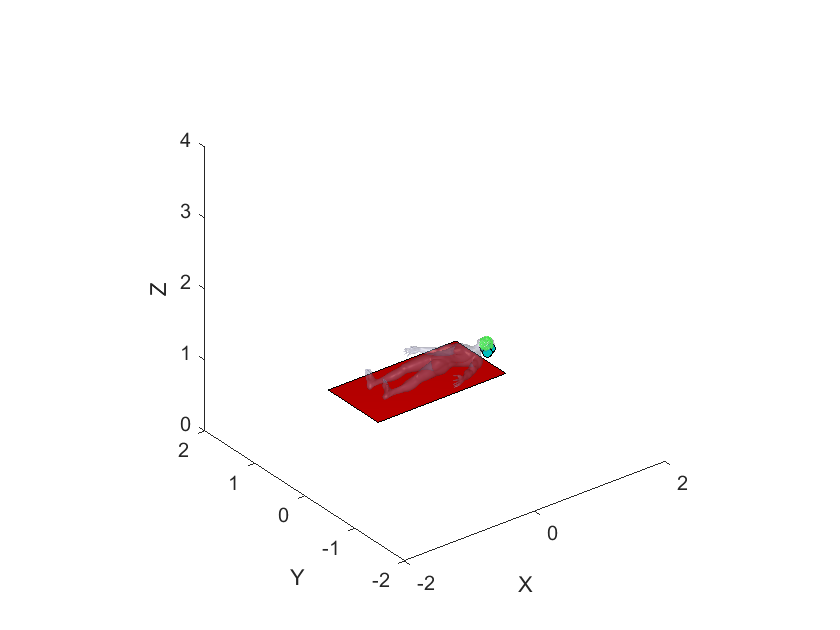

% [VS,FS] = stlRead('Crani.stl');
RFC = transl(person_height/2-0.11,-0.005,table_h+0.1425)*troty(90, 'deg')*trotz(-90, 'deg')*trscale(0.001);
% VS2 = h2e(RFC*e2h(VS'))';
% 
% p = patch('Faces',FS,'Vertices',VS2, 'FaceColor',       [0.2 1 0.2], ...
%          'EdgeColor',       'none',        ...
%          'FaceLighting',    'flat',     ...
%          'AmbientStrength', 0.95, ...
%          'FaceAlpha', 0.75);

RFI = RFC * trscale(1, 1, 1.4) * troty(180, 'deg') * transl(-125, -145, -65);
fiducidals = load('fiducidals.csv');
fiducidals = h2e(RFI * e2h(fiducidals'))';
hold on
scatter3(fiducidals(:, 1), fiducidals(:, 2), fiducidals(:, 3), 24, ...
    'MarkerEdgeColor','k', ...
    'MarkerFaceColor',[0 .75 .75])  

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

tumor = load('tumor.csv');


t_even = tumor(1:2:end, :);
t_odd = tumor(2:2:end, :);

t_n1 = [t_even(:, 1) t_odd(:, 2) t_even(:, 3)];
t_n2 = [t_odd(:, 1) t_even(:, 2) t_even(:, 3)];

tumor = [tumor; t_n1; t_n2];

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

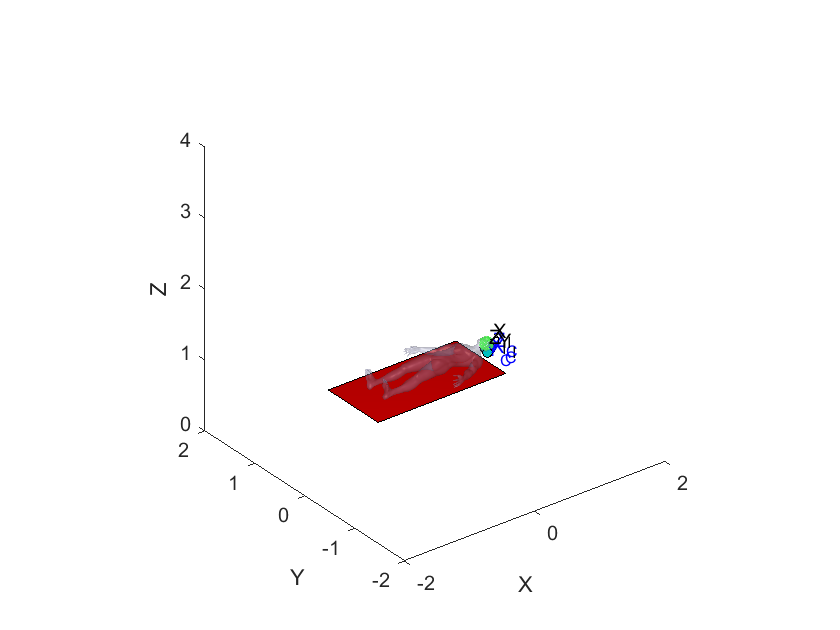

trplot(RFC, 'length', 100, 'color', 'b', 'frame', 'C')
trplot(RFI, 'length', 100, 'color', 'k', 'frame', 'I')

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

mdl_puma560_Craigh
%EE=p560Craigh.fkine(qz)
RFR = transl(1.5, 0, 2) * trotz(180, 'deg');
p560Craigh.tool = SE3(0, 0, 0.2);
p560Craigh.base = RFR;
%p560Craigh.plot(qz, 'zoom', 2)
p560Craigh

 
p560Craigh = 
 
Puma560-Craigh [Unimation]:: 6 axis, RRRRRR, modDH, slowRNE      
 - Craigh;                                                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|          0|    -1.5708|          0|
|  3|         q3|    0.15005|     0.4318|          0|          0|
|  4|         q4|     0.4318|     0.0203|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|    -1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (1.5, 0, 2), RPY/xyz = (-180, 0, 0) deg             
tool:    t = (0, 0, 0.2), RPY/xyz = (0, 0, 0) deg                
 


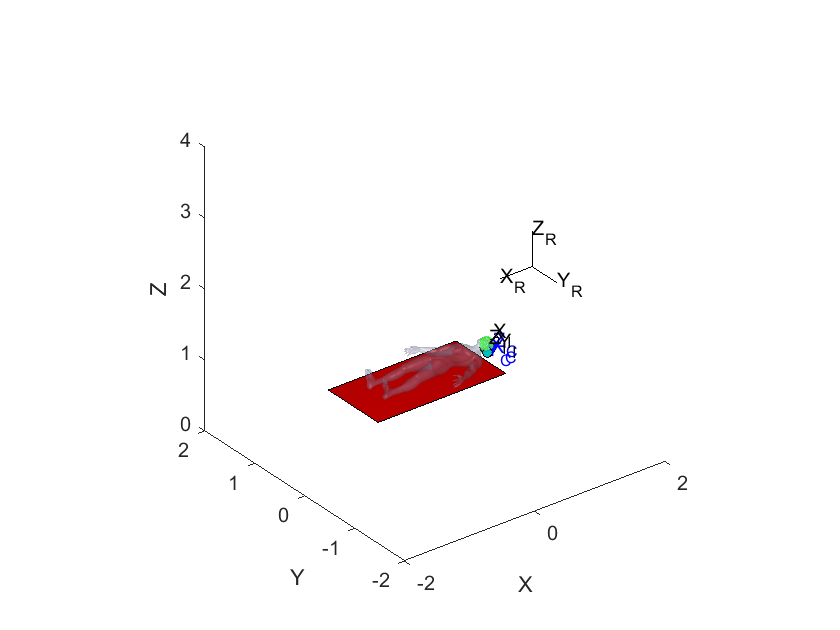


trplot(RFR, 'length', 0.5, 'color', 'k', 'frame', 'R')

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

tumor = h2e(RFI * e2h(tumor'))';

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

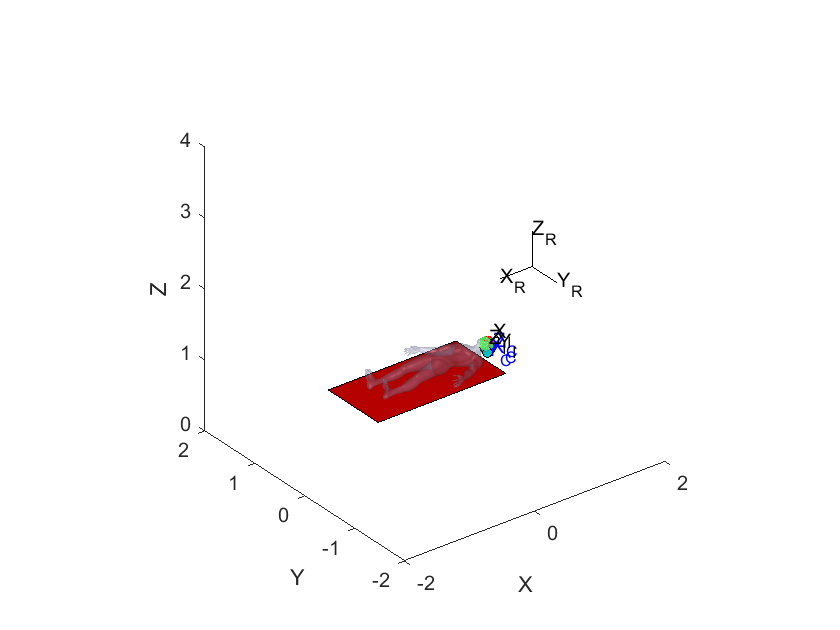

scatter3(tumor(:, 1), tumor(:, 2), tumor(:, 3), 12, 'r', 'filled')

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%biopsy

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

trepanation

Error using matlab.graphics.primitive.Group/set
Invalid or deleted object.

Error in SerialLink/animate (line 150)
                set(handle, 'UserData', h);

Error in SerialLink/plot (line 299)
    robot.animate(qq

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts here.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here